
$$x=V_1 -V_2$$



$$x=I_1 R_3 -I_2 R_4$$



$$I_2 \left(R_2 +R_4 \right)=I_1 \left(R_1 +R_3 \right)$$



$$I_1 \left(1+\frac{R_1 +R_3 }{R_2 +R_4 }\right)=V_{\textrm{in}} \left(\frac{1}{R_1 +R_3 }+\frac{1}{R_2 +R_4 }\right)$$



$$x=I_1 \left(R_3 -R_4 \frac{R_1 +R_3 }{R_2 +R_4 }\right)$$



$$x=V_{\textrm{in}} \frac{\left(\frac{1}{R_1 +R_3 }+\frac{1}{R_2 +R_4 }\right)\left(R_3 -R_4 \frac{R_1 +R_3 }{R_2 +R_4 }\right)}{1+\frac{R_1 +R_3 }{R_2 +R_4 }}$$


syms Vin R1 R2 R3 R4
x = Vin*((R1 + R3)^(-1) + (R2 + R4)^(-1))*(R3 - R4*(R1 + R3)/(R2 + R4))/(1 + (R1 + R3)/(R2 + R4));
R3_vals = logspace(-2, 3, 100);
x = subs(x, R3, R3_vals);
x = subs(x, Vin, 5)

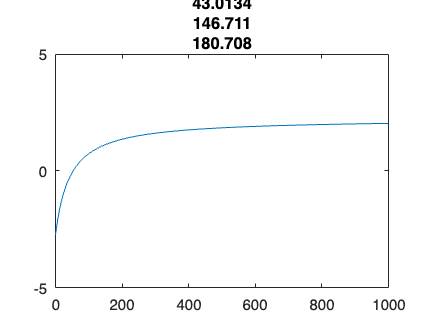

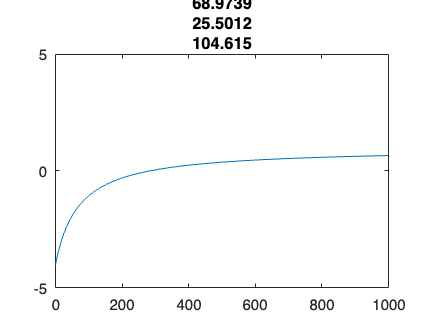

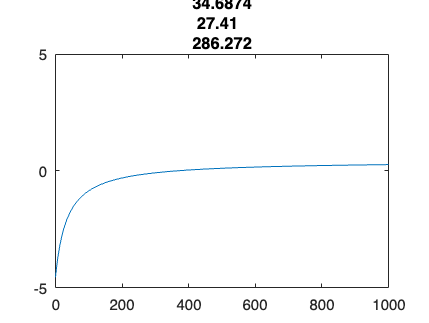

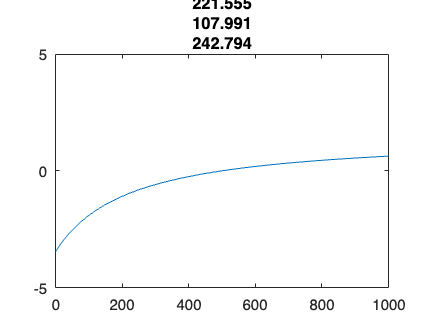

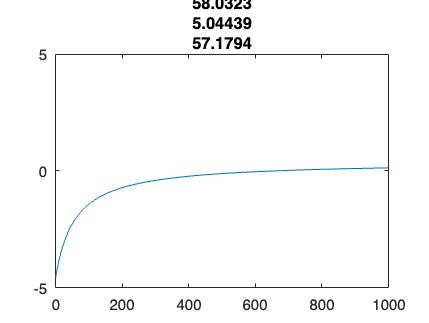

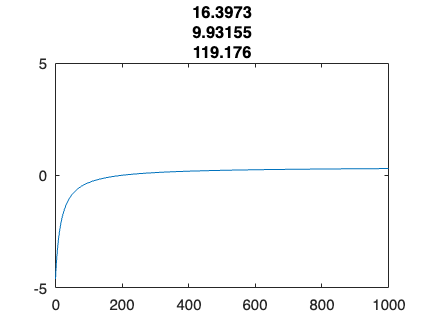

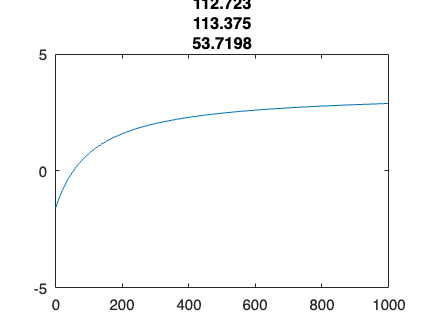

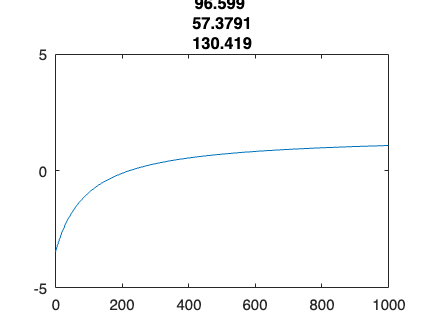

for i=1:15
    iterator = 1;
    x_vals = x;
    constR_vals = 80*abs(randn(1, 3));
    for R=[R1, R2, R4]
        x_vals = subs(x_vals, R, constR_vals(iterator));
        iterator = iterator + 1;
    end
    figure()
    plot(R3_vals, double(x_vals))
    title(constR_vals)
    xlim([0, 1000])
    ylim([-5, 5])
end

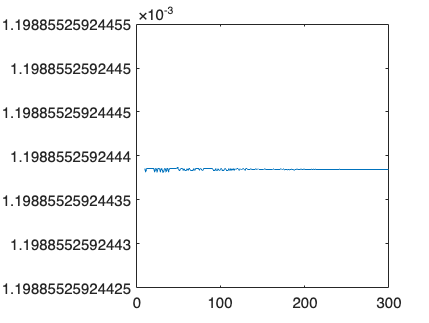

R2_vals = linspace(10, 300, 300);
metric = zeros(1, 300);
for i = 1:length(R2_vals)
    iterator = 1;
    x_vals = x;
    constR_vals = [500, 150, R2_vals(i)];
    for R=[R1, R2, R4]
        x_vals = subs(x_vals, R, constR_vals(iterator));
        iterator = iterator + 1;
    end
    x_vals = double(x_vals);
    metric(i) = (x_vals(100) - x_vals(99))/(R3_vals(100) - R3_vals(99));
end
plot(R2_vals, metric)

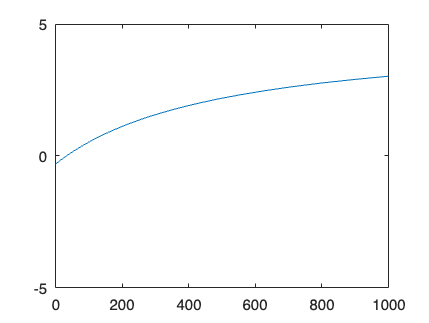

iterator = 1;
x_vals = x;
constR_vals = [500, 300, 20];
for R=[R1, R2, R4]
    x_vals = subs(x_vals, R, constR_vals(iterator));
    iterator = iterator + 1;
end
x_vals = double(x_vals);
plot(R3_vals, x_vals)
xlim([0, 1000])
ylim([-5, 5])

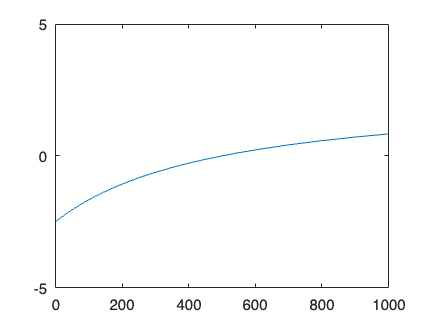

% xscale('log')

iterator = 1;
x_vals = x;
constR_vals = [500, 50, 50];
for R=[R1, R2, R4]
    x_vals = subs(x_vals, R, constR_vals(iterator));
    iterator = iterator + 1;
end
x_vals = double(x_vals);
plot(R3_vals, x_vals)
xlim([0, 1000])
ylim([-5, 5])

% xscale('log')

syms Vin R1 R2 R3 R4 x
x_test = Vin*((R1 + R3)^(-1) + (R2 + R4)^(-1))*(R3 - R4*(R1 + R3)/(R2 + R4))/(1 + (R1 + R3)/(R2 + R4));
x_test = subs(x_test, R1, 500);
x_test = subs(x_test, R2, 20);
x_test = subs(x_test, Vin, 5.12);
x_test = subs(x_test, R4, 20)

$$x\_test = \frac{128\,\left(\frac{R_{3}}{2}-250\right)\,\left(\frac{1}{R_{3}+500}+\frac{1}{40}\right)}{25\,\left(\frac{R_{3}}{40}+\frac{27}{2}\right)}$$

R3 = solve(x == x_test, R3)

$$R3 = -\frac{12500\,x+32000}{25\,x-64}$$